# LAB 4: SIMULATION OF ANGULAR VELOCITY CONTROL FOR A DC MOTOR

%---------------------------------------
% Fill in your group number.
GroupNumber = 29;
% Fill in your student Name and ID.
Students(1).Name = 'Patrick Erath';
Students(1).ID = '260719203';
Students(2).Name = 'Ahmed Said';
Students(2).ID = '260665291';
%---------------------------------------

## **0. Objectives**

In this lab, we will run different simulation experiments to track a desired reference signal with a simulated DC Motor. We will first run an open-loop experiment, then we will use state feedback to control the angular velocity of DC motor.

## **1. A State-Space Representation of DC Motor**

A DC motor is a device that converts armature current into mechanical torque. A schematic of a DC motor is shown in the following

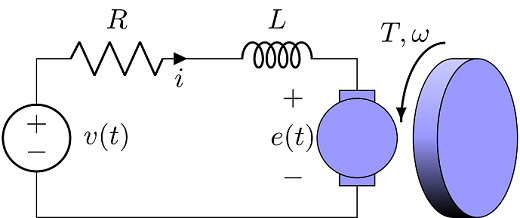

We can model the DC motor using the armature current $i$ and the angular speed $\omega$. The dynamics of the DC motor are given by the following two coupled differential equations:


$$ J \displaystyle \frac{d \omega}{dt} + b \omega = K_t i $$



$$ L \displaystyle \frac{d i}{dt} + R i = v - K_e \omega $$


where the parameters are defined as follow

Param.Kt = 0.034; % Torque proportionality constant (Kg m2 /s2/A) (N.m/A)
Param.Ke = 0.034; % Back electromotive proportionality constant (V/rad/s)
Param.L = 0.018; % Electric inductance (H)
Param.R = 8.4; % Terminal resistance (Ohm)
Param.J = 2e-05; % Rotor moment of inertia (kg.m2)
Param.b = 1e-06; % Rotor viscous friction constant (Kg.m2/s) (N.m.s)

From these differential equations we can represent the DC Motor model by the following state-space representation


$$ \displaystyle \frac{d}{dt}x(t) = \pmatrix{ -\displaystyle \frac{b}{J}
& \displaystyle \frac{K_t}{J} \cr -\displaystyle \frac{K_e}{L} &
-\displaystyle \frac{R}{L} } x(t) + \pmatrix{ 0 \cr \displaystyle
\frac{1}{L} } v(t) $$


where $v(t)$ is the voltage and the state vector contains the angular velocity $\omega(t)$ and the current $i(t)$


$$ x(t) = \pmatrix{ \omega(t) \cr i(t) } $$


## *Question 1 (1 mark)*

Write the state-space representation of the DC Motor (Only A and B matrices).

A = [-Param.b/Param.J Param.Kt/Param.J; -Param.Ke/Param.L -Param.R/Param.L]

A =    1.0e+03 *

   -0.0000    1.7000
   -0.0019   -0.4667


B = [0; 1/Param.L]

B =          0
   55.5556


## **2. Desired specifications**

The objective of this lab is to track a reference signal $\omega_{ref}$ while satisfying the following requirements:

- Overshoot less than 10%.

- 5%-settling time less than 0.2 seconds.

- Steady state gain of 1 $\pm$ 5%.

The Reference angular velocity is defined by the following:


$$ \omega_{ref}(t) = \begin{cases}  0, & 0 \leq t < 1 \\ 50,  & t \geq
5\end{cases}$$


In `MATLAB` we define $\omega_{ref}$ by:

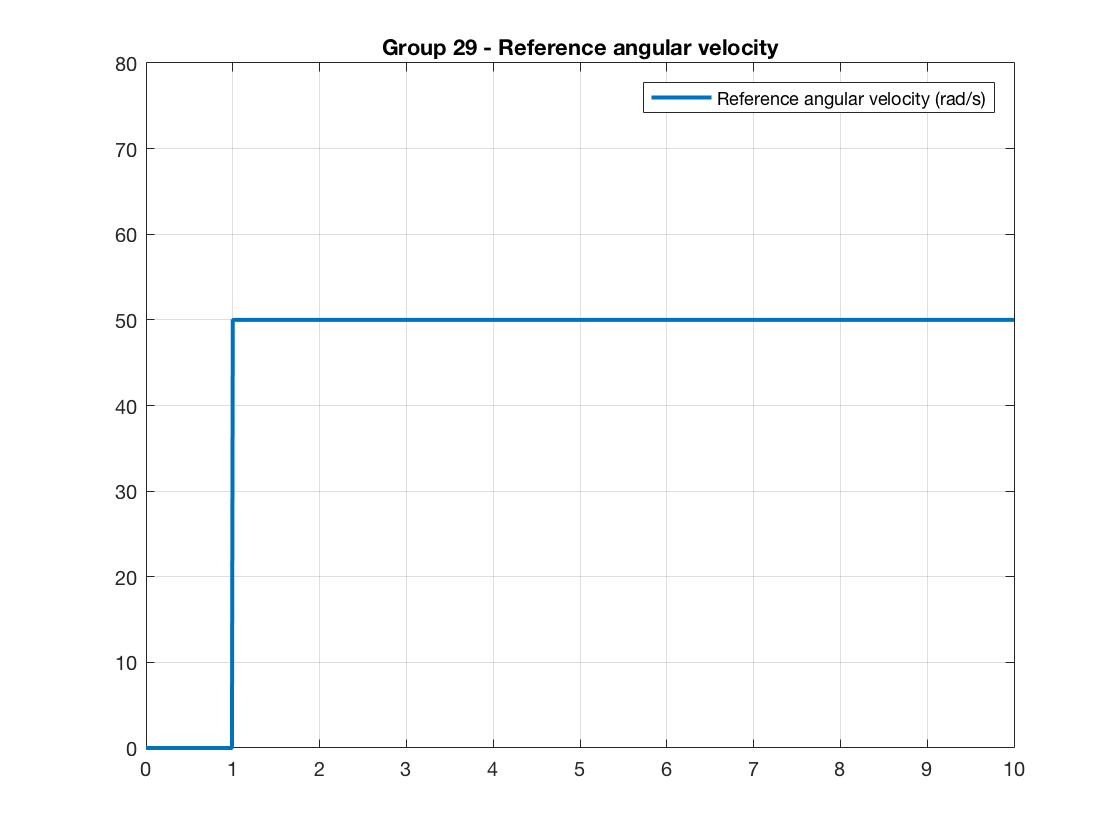

T = 10; % Simulation duration
dt = 0.01; % Simulation step time
t = (0:dt:T)'; % Time array
TStart = 1; % Step start
wRef = zeros(size(t));
wRef(t >= TStart) = 50; % rad/s

figure;
clf;
plot(t, wRef, 'LineWidth', 2.0)
legend('Reference angular velocity (rad/s)');
xlim([0, T])
ylim([0, 80])
title(sprintf('Group %d - Reference angular velocity', GroupNumber));
grid on

## **3. Open-loop Simulation Experiment**

The state-space open-loop system is presented below.

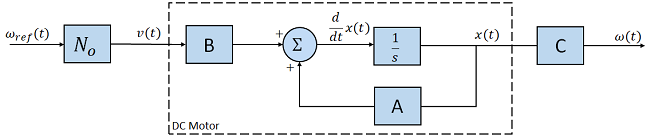

Note that if we think of the angular velocity $\omega(t)$ as the output of this system, then $C = \pmatrix{1 & 0}$ and


$$ \omega(t) = C x(t) $$


In this case, the transfer function from the voltage $v(t)$ to the angular velocity $\omega(t)$ is given by


$$ G_o(s) = C (s I - A)^{-1} B $$


In `MATLAB`, we can find the transfer function of a state-space model using the function `ss` and `tf`, as shown below.

C = [1, 0];
D = 0;
Go = ss(A, B, C, D)


Go =
 
  A = 
           x1      x2
   x1   -0.05    1700
   x2  -1.889  -466.7
 
  B = 
          u1
   x1      0
   x2  55.56
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



tf(Go)


ans =
 
        9.444e04
  --------------------
  s^2 + 466.7 s + 3234
 
Continuous-time transfer function.



## *Question 2 (1 mark)*

Recall that the DC gain can be obtained from a laplace transfer function, by setting the laplace variable $s$ to zero. From the state-space model representation $(A,\,B,\,C,\,D)$, calculate the DC gain.

dcGainOL = C*inv(-A)*B

dcGainOL = 29.1996

Observe that if the open-loop system is a stable system. The DC Motor will responded to a reference step signal without using a controller. However, the response will be determined by the eigenvalues of the open-loop $A$ matrix (or equivalently, the poles of the open-loop transfer function).

## *Question 3 (1 mark)*

Determine the poles of the open-loop transfer function from the state-space matrix $A$ (Hint: `help eig`). Is the system stable ? (Justify your answer.)

E = eig(A)

E =    -7.0363
 -459.6804


p1 = -7.0363

p1 = -7.0363

p2 = -459.6804

p2 = -459.6804

% The system is stable because both poles are in the left help plane (LHP)
% Thus, the open-loop transfer function has NO poles on the jw-axis OR in the RHP

Following a fixed input $v_0$ the angular velocity $\omega$ will attain a steady angular velocity $\omega_{\infty} = DC_{gain} v_0$.

We can simulate the response of an LTI system to an arbitrary input using the `lsim` function.

## *Question 4 (0.5 mark)*

Complete the following code to simulate the response of the system to a 1 volt input signal, and plot the results.

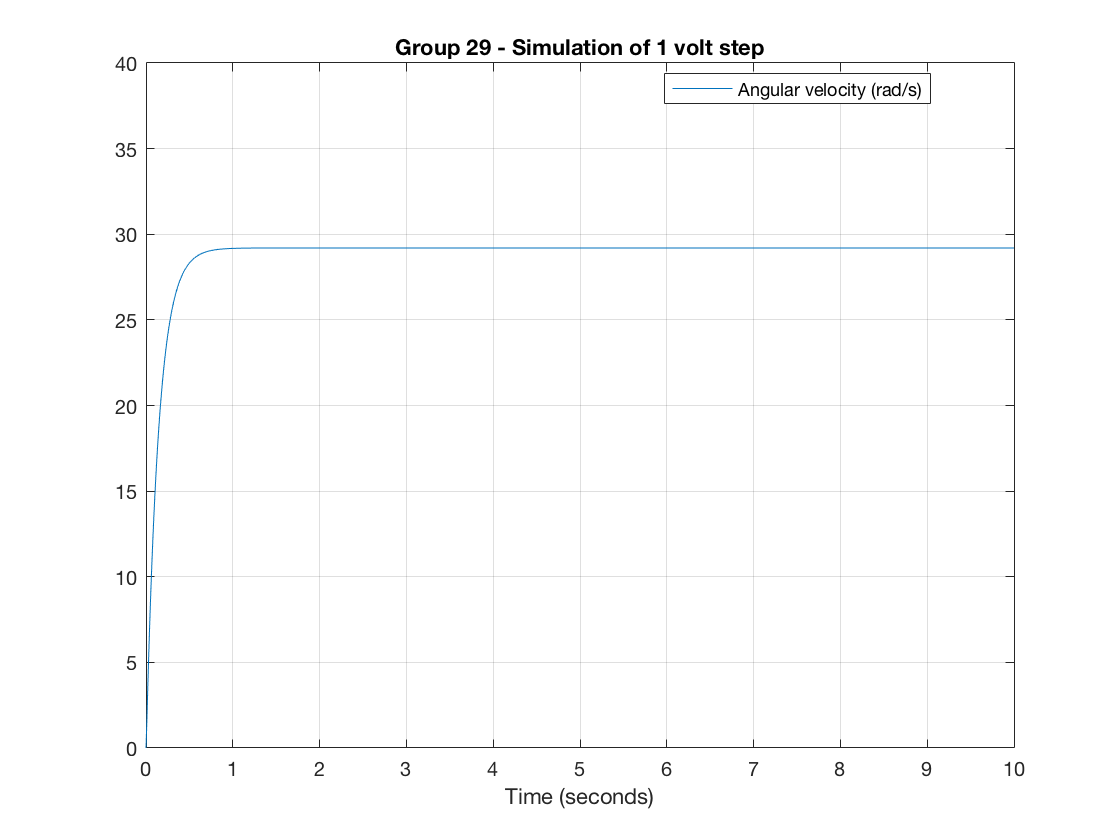

v = ones(size(t)); % create a signal with one volt.
w = lsim(Go, v, t);

% Plot results
figure;
clf;

% [Answer here] plot the angular velocity w
plot(t, w)
legend('Angular velocity (rad/s)', ...
    'location', 'best');
xlim([0, T])
ylim([0, 40])
xlabel('Time (seconds)')
title(sprintf('Group %d - Simulation of 1 volt step', GroupNumber));
grid on

In open-loop we can generate the voltage $v$ from $\omega_{ref}$ through the gain $N_o$.


$$ v(t) = N_o \omega_{ref}(t) $$


## *Question 5 (1 mark)*

Find the value of $N_o$ such the the final value of the angular velocity output $\omega$ is the same as $\omega_{ref}$ (i.e. 50 rad/s)

No = 1/dcGainOL

No = 0.0342


% The voltage is generated from wRef and No
v = No * wRef;

% [Answer here] Simulate the output angular velocity using lsim

w = lsim(Go, v, t)

w =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0




% Plot results
figure;
clf;

% [Answer here] Superpose the angular velocity w and the the reference wRef
xlabel('Time (seconds)')
legend('Angular velocity (rad/s)', ...
    'Reference angular velocity (rad/s)', ...
    'location', 'best');

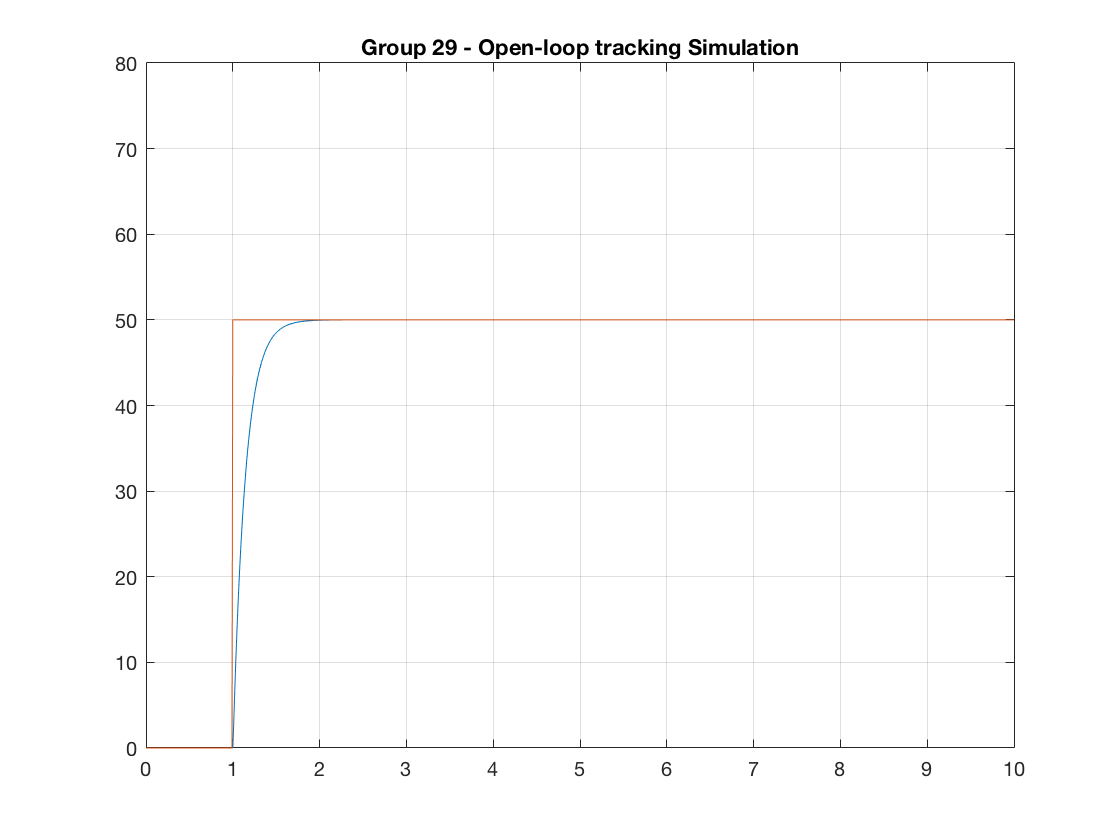

plot(t, w)
hold on;
plot(t, wRef)
xlim([0, T])
ylim([0, 80])
title(sprintf('Group %d - Open-loop tracking Simulation', GroupNumber));
grid on

## *Question 6 (0.5 marks)*

Based on the plot above, determine if all the requirements are satisfied. Justify your answer.

Answer here:

**Based on the plot above, it can be seen the angular velocity and the reference wRef are have the same initial and final value, but not the same slope inbetween (between 1 and 2 seconds the two graphs differ).**

**Nonetheless; the graph is a step function and wRef is indeed 50 rad/s thus the requirements are indeed satisfied.**

## **4. Closed-Loop Simulation Experiment**

The closed-loop system is presented in the following figure.

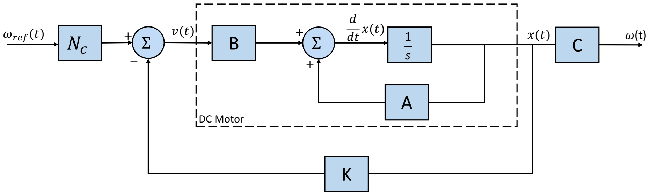

The full-state feedback control law is defined as follow


$$v(t) = N_c \omega_{ref} - K x(t)$$


where gain $K$ is a 1 by 2 matrix and the gain $N_c$ is forward gain that will ensure achieving $\omega_{ref}$ at steady state.

Actually, this diagram is equivalent to an open-loop diagram but with a different state transition matrix $A_{cl} = A-BK$

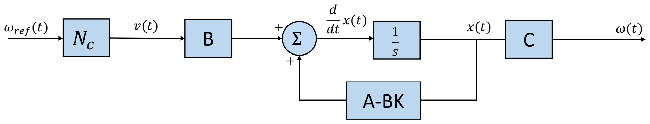

Doing a state feedback with gain $K$ is equivalent to changing the system dynamics from $A$ to $A-BK$. Recall that the eigenvalues of a state transition matrix $A$ are the poles of the system.

We want to choose $K$ to specify the new poles of the closed-loop system $A-BK$ in a way that satisfies the desired specifications

- Overshoot less than 10%.

- 5%-settling time less than 0.2 seconds.

Then we will choose $N_c$ similarly to the open-loop section to satisfy the steady state requirements:

- Steady state gain of 1 $\pm$ 5%.

## *Question 7 (2 marks)*

Calculate the desired poles that satisfies the specifications (Use formula sheet for transient response of 2nd order system in myCourses if needed):

% Define Variables
OS=0.1

OS = 0.1000

Ts=0.2

Ts = 0.2000


%Solve for damping coefficient, wn and wd
z=(-log(OS))/(sqrt((pi)^2+(log(OS))^2))

z = 0.5912

sigma1=3/Ts

sigma1 = 15

wn=sigma1/z

wn = 25.3741

wd=wn*(sqrt(1-(z)^2))

wd = 20.4656

%wn=wd/(sqrt(1-(z)^2))

% Define Denomiantor
s=tf('s')


s =
 
  s
 
Continuous-time transfer function.



D1=s^2+2*z*s+(wn)^2


D1 =
 
  s^2 + 1.182 s + 643.8
 
Continuous-time transfer function.




% Solve for poles
p1d=-sigma1+wd*i

p1d =  -15.0000 +20.4656i


p2d=-sigma1-wd*i

p2d =  -15.0000 -20.4656i


Instead of manual calculation of the value of the gain $K$ that place the poles of $A-BK$ at [p1d, p2d], we will use the `place` command to calculate the gain $K$

K = place(A, B, [p1d, p2d]);

## *Question 8 (1 mark)*

The closed-loop transfer function is


$$ G_c(s) = C (sI - (A-BK))^{-1} B $$


- What is the value of the DC gain of the closed-loop system.

- What is the value $N_c$ needed to compensate for the DC gain of the closed-loop system.

dcGainCL=C*(-inv(A-B*K))*B

dcGainCL = 146.6887

Nc=1/dcGainCL

Nc = 0.0068

## *Question 9 (1 mark)*

Complete the following to simulate angular velocity control with state feedback that tracks the desired $\omega_{ref}$.

[Answer here] Define the closed-loop system using ss

Gc = ss(A-B*K, B, C, D)


Gc =
 
  A = 
            x1       x2
   x1    -0.05     1700
   x2  -0.3779   -29.95
 
  B = 
          u1
   x1      0
   x2  55.56
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



stepinfo(Gc)

ans = struct with fields:
        RiseTime: 0.0723
    SettlingTime: 0.2335
     SettlingMin: 132.3905
     SettlingMax: 161.3576
       Overshoot: 10.0000
      Undershoot: 0
            Peak: 161.3576
        PeakTime: 0.1535


% [Answer here] Simulate the output angular velocity using lsim
v = wRef * Nc

v =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


w = lsim(Gc, v, t)

w =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


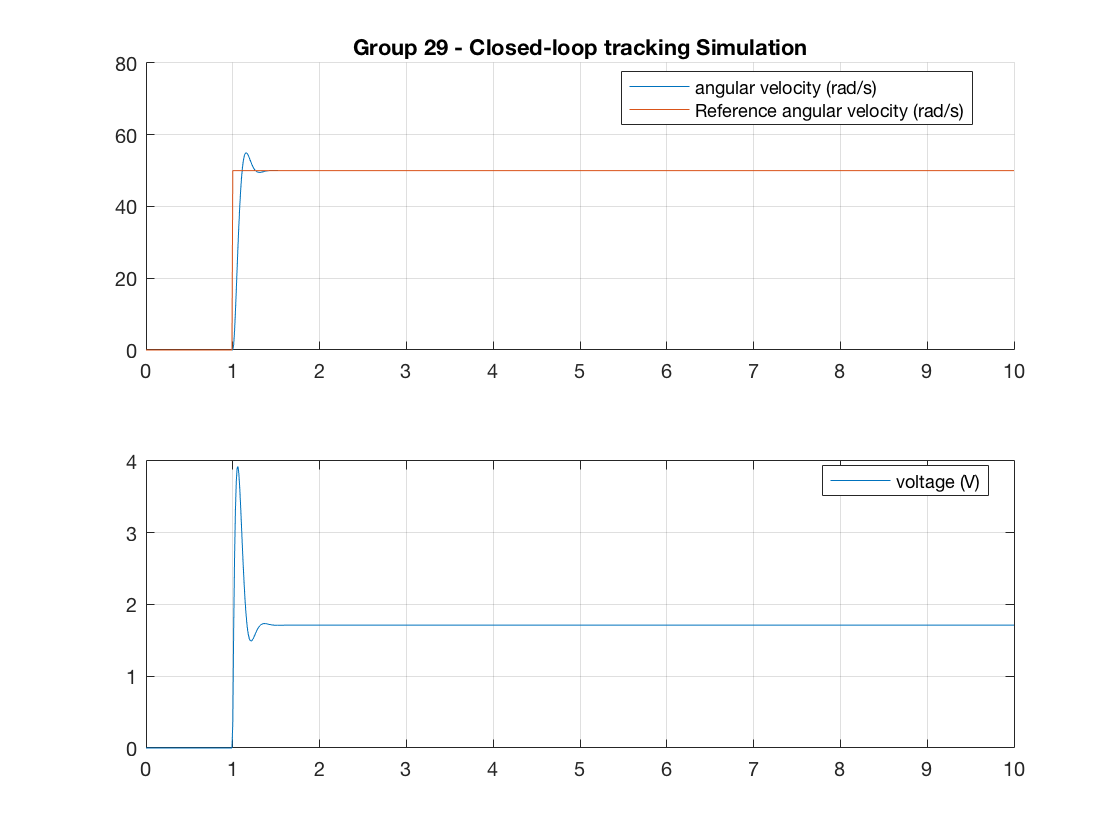



% We also simulate the voltage for visualization
v = -lsim(ss(Gc.A, Gc.B, eye(2), Gc.D), Nc*wRef, t) * K' + Nc * wRef;

figure;
clf;

subplot(2, 1, 1)
% [Answer here] Superpose angular velocity w with the angular velocity
% reference
hold on;
plot(t, w)
plot(t, wRef)
hold off;
legend('angular velocity (rad/s)', ...
    'Reference angular velocity (rad/s)', ...
    'location', 'best');
xlim([0, T])
ylim([0, 80])
grid on
title(sprintf('Group %d - Closed-loop tracking Simulation', GroupNumber));

subplot(2, 1, 2)
% [Answer here] Plot the voltage
plot(t, v)
legend('voltage (V)', 'location', 'best');
xlim([0, T])
grid on

## *Question 10 (1 marks)*

Based on the plot above, determine if all the requirements are satisfied. Justify your answer.

% Answer here : Based on the plot above, it can be seen that the
% overshoot for Gc is approximately 9.999%, with the requirement
% being that the overshoot be under 10%, this condition was satisfied.
% Furthermore, it can be seen that settling time is approximately 0.2 seconds
% Lastly, the angular frequency is also approximately 50 rad/s, 
% which in conclusion confirms that all the requirements were satisfied